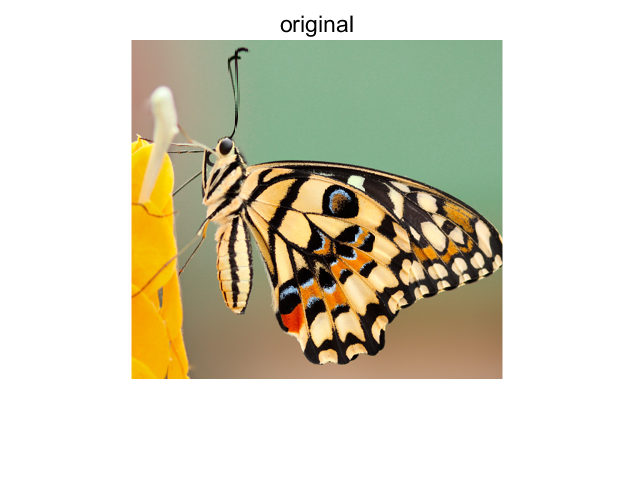

close all;
clear all;
% read image
original = im2double(imread('tiger.png'));
[H,W,channel] = size(original);
imshow(original)
title('original')


% To compatible with gray images
if channel == 1 
    original = cat(3,original,original,original);
end

%Parameter setting
%For ALL filters
r = 3;
% For gaussian filter
sigma = 4;
% For guided filter and bilateral filter  
epsilon = 0.01;

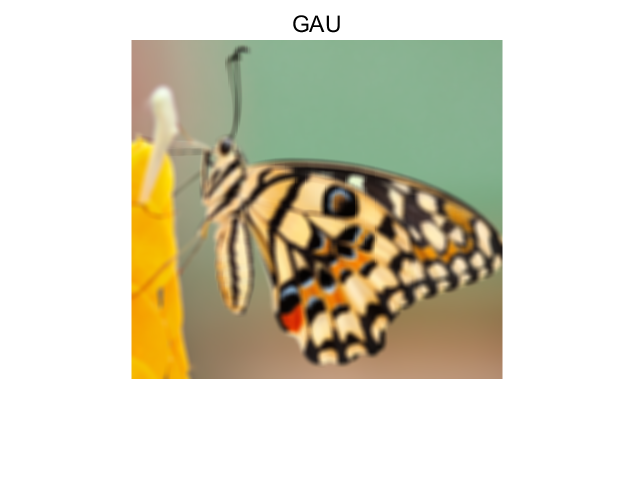

% Gaussian Filter (GAU)
for c = 1 : channel
    GAU_res(:,:,c) = gaussianfilter(original(:,:,c), r, sigma);
end
imshow(GAU_res)
title('GAU')

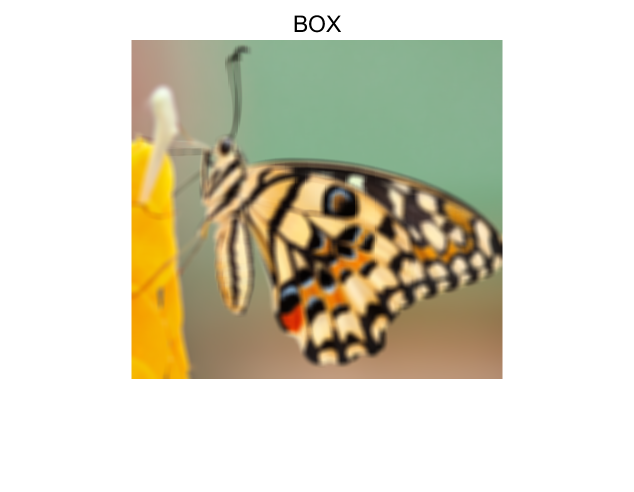

% Box Filter (BOX)
weight = boxfilter(ones(H, W),r);
for c = 1 : channel
    BOX_res(:,:,c) = boxfilter(original(:,:,c), r);
    BOX_res(:,:,c) = BOX_res(:,:,c)./weight;
end
imshow(BOX_res)
title('BOX')

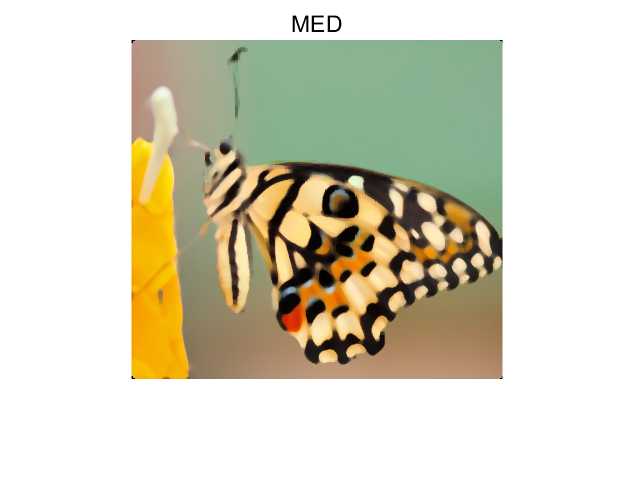

% Median Filter (MED)
for c = 1 : channel
    MED_res(:,:,c) = medfilt2(original(:,:,c),[2*r+1,2*r+1]);
end
imshow(MED_res)
title('MED')

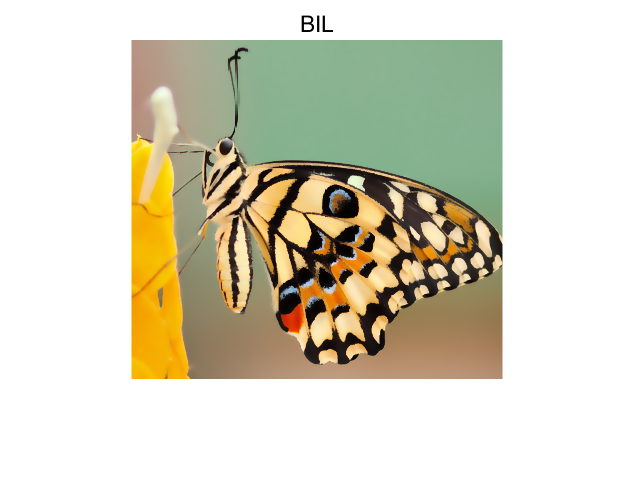

% Bilateral Filter (BIL)
for c = 1 : channel
    BIL_res(:,:,c) = bfilter2(original(:,:,c),r,[r,sqrt(epsilon)]);
end
imshow(BIL_res)
title('BIL')

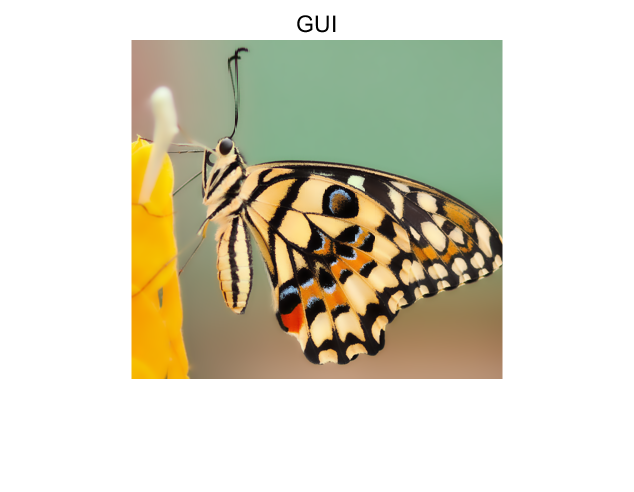

%Guided Filter (GUI)
for c = 1 : channel
    GUI_res(:,:,c) = guidedfilter(original(:,:,c),original(:,:,c),r,epsilon);
end
imshow(GUI_res)
title('GUI')